# Comparison of background treatment approaches

#### Author: Luis Fabregas

Here we will discuss how to use the API to compare different approaches which have established for the treatment of the background function in dipolar signals (see [this reference](https://pubs.rsc.org/en/content/articlelanding/2020/cp/c9cp06111h#!divAbstract) for detailed information).

## Data simulation

Let's consider a dipolar signal arising from some Gaussian-shaped distance distribution with a relatively fast decaying stretched exponential background. We will set the modulation depth to 40% and add some noise to it.

clear,clc,clf

%Model input parameters
k = 0.9;
d = 2.85;
lam = 0.4;
rmean1 = 3.5;
w1 = 0.25;
rmean2 = 4.0;
w2 = 0.45;
A = 0.45;

%Construct the axes
t = linspace(0,5,400);
r = linspace(2,5,100);

%Generate distance distribution and background
P = rd_twogaussian(r,[rmean1 w1 rmean2 w2 A]);
B = td_strexp(t,[k d]);

%Generate dipolar signals
V = dipolarsignal(t,r,P,'noiselevel',0.01,'moddepth',lam,'background',B);

## Background treatment

Now in order to treat the background we first need to know its parameters. Usually we would have to fit the background either as a two-way approach (using `fitbackground`) or by means of bilevel optimization. However, in this example we will assume that we know the background parameters exactly to remove the effects of background parameters misfits. 

### Division

Knowing the background function we can first consider the approach of background division. Once the signal has been processed into a dipolar-evolution function, we us Tikhonov regularization to infer the distance distribution.

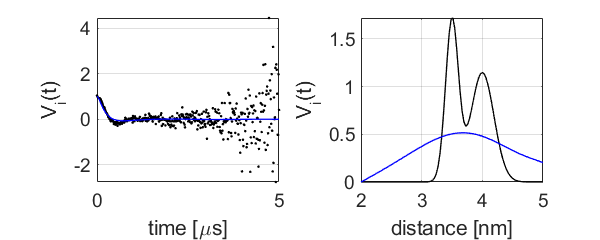

%"Correct" the signal for its background via diivision
Vdiv = V./B;
%Correct for the unmodulated part of the signal
Vdiv = (Vdiv - (1-lam))/lam;

%Generate the dipolar kernel
K = dipolarkernel(t,r);

%Run Tikhonov regularization
Pdiv = fitregmodel(Vdiv,K,r,'tikh','aic');

%Get the time-domain fit
Vfit = K*Pdiv;

%Plotting
figure('position',[0 0 600 240]),clf

subplot(121)
plot(t,Vdiv,'k.',t,Vfit,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('time [\mus]')
ylabel('V_i(t)')
set(gca,'FontSize',14)

subplot(122)
plot(r,P,'k',r,Pdiv,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('distance [nm]')
ylabel('V_i(t)')
set(gca,'FontSize',14)

### Subtraction

Next we will try background subtraction. 

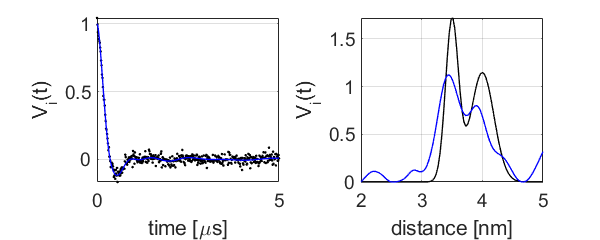

%"Correct" the signal for its background via subtraction
Vsub = V - (1 - lam)*(B);
Vsub = Vsub/lam;

%Generate the dipolar kernel
K = dipolarkernel(t,r);

%Run Tikhonov regularization
Psub = fitregmodel(Vsub,K,r,'tikh','aic');

%Get the time-domain fit
Vfit = K*Psub;

%Plotting
figure('position',[0 0 600 240]),clf

subplot(121)
plot(t,Vsub,'k.',t,Vfit,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('time [\mus]')
ylabel('V_i(t)')
set(gca,'FontSize',14)

subplot(122)
plot(r,P,'k',r,Psub,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('distance [nm]')
ylabel('V_i(t)')
set(gca,'FontSize',14)

### Kernel with background

Next we will use the (recommended) practice of including the background information into the dipolar kernel to fit the primary data directly without the need for background correction.

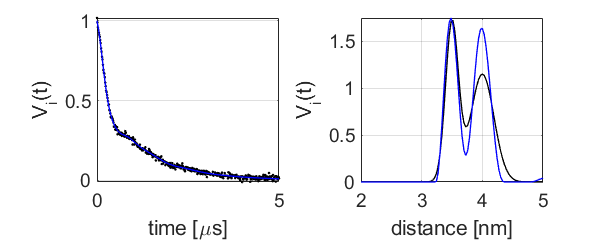

%Generate the dipolar kernel with the background
KB = dipolarkernel(t,r,lam,B);

%Run Tikhonov regularization
PKb = fitregmodel(V,KB,r,'tikh','aic');

%Get the time-domain fit
Vfit = KB*PKb;

%Plotting
figure('position',[0 0 600 240]),clf

subplot(121)
plot(t,V,'k.',t,Vfit,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('time [\mus]')
ylabel('V_i(t)')
set(gca,'FontSize',14)

subplot(122)
plot(r,P,'k',r,PKb,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('distance [nm]')
ylabel('V_i(t)')
set(gca,'FontSize',14)

### Kernel with square-root of background

As mentioned here, another optimal approach involves the partial correction of the dipolar signal by square-root of the backgrund and introduction of the other squared-root of the background into the kernel.  

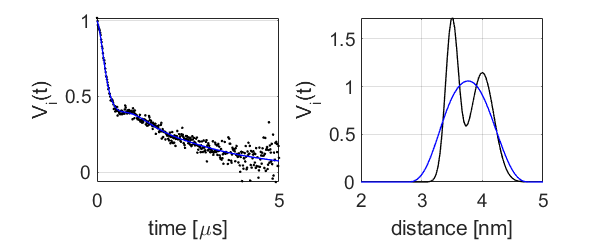

%Generate the dipolar kernel with the background
KB = dipolarkernel(t,r,lam,sqrt(B));
Vsqrt = V./sqrt(B);

%Run Tikhonov regularization
PKb = fitregmodel(Vsqrt,KB,r,'tikh','aic');

%Get the time-domain fit
Vfit = KB*PKb;

%Plotting
figure('position',[0 0 600 240]),clf

subplot(121)
plot(t,Vsqrt,'k.',t,Vfit,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('time [\mus]')
ylabel('V_i(t)')
set(gca,'FontSize',14)

subplot(122)
plot(r,P,'k',r,PKb,'b','LineWidth',1)
grid on,axis tight,box on
xlabel('distance [nm]')
ylabel('V_i(t)')
set(gca,'FontSize',14)